# Clear workspace and command window

clear;  % Clears all variables from the workspace to start fresh
clc;  % Clears the command window


## Data Collection

% Scale factor to resize images for computational efficiency
scaleFactor = 0.5;  % Reduces the size of the images by 50% to speed up processing

% Load and resize Landsat 8 bands (input files)
band1 = imresize(im2double(imread('LC08_L1TP_113082_20211206_20211206_01_RT_B1.tif')), scaleFactor);
band2 = imresize(im2double(imread('LC08_L1TP_113082_20211206_20211206_01_RT_B2.tif')), scaleFactor);
band3 = imresize(im2double(imread('LC08_L1TP_113082_20211206_20211206_01_RT_B3.tif')), scaleFactor);
band4 = imresize(im2double(imread('LC08_L1TP_113082_20211206_20211206_01_RT_B4.tif')), scaleFactor);
band5 = imresize(im2double(imread('LC08_L1TP_113082_20211206_20211206_01_RT_B5.tif')), scaleFactor);
band6 = imresize(im2double(imread('LC08_L1TP_113082_20211206_20211206_01_RT_B6.tif')), scaleFactor);
band7 = imresize(im2double(imread('LC08_L1TP_113082_20211206_20211206_01_RT_B7.tif')), scaleFactor);
band9 = imresize(im2double(imread('LC08_L1TP_113082_20211206_20211206_01_RT_B9.tif')), scaleFactor);
% Reads Landsat 8 images (spectral bands) and resizes them by the scale factor for processing efficiency


## Data Preparation

% Scale factor to resize images for computational efficiency
scaleFactor = 0.5;  % Reduces the size of the images by 50% to speed up processing

% Load and resize Landsat 8 bands (input files)
band1 = imresize(im2double(imread('LC08_L1TP_113082_20211206_20211206_01_RT_B1.tif')), scaleFactor);
band2 = imresize(im2double(imread('LC08_L1TP_113082_20211206_20211206_01_RT_B2.tif')), scaleFactor);
band3 = imresize(im2double(imread('LC08_L1TP_113082_20211206_20211206_01_RT_B3.tif')), scaleFactor);
band4 = imresize(im2double(imread('LC08_L1TP_113082_20211206_20211206_01_RT_B4.tif')), scaleFactor);
band5 = imresize(im2double(imread('LC08_L1TP_113082_20211206_20211206_01_RT_B5.tif')), scaleFactor);
band6 = imresize(im2double(imread('LC08_L1TP_113082_20211206_20211206_01_RT_B6.tif')), scaleFactor);
band7 = imresize(im2double(imread('LC08_L1TP_113082_20211206_20211206_01_RT_B7.tif')), scaleFactor);
band9 = imresize(im2double(imread('LC08_L1TP_113082_20211206_20211206_01_RT_B9.tif')), scaleFactor);
% Reads Landsat 8 images (spectral bands) and resizes them by the scale factor for processing efficiency

% Solar irradiance values for each band (in W/m^2/um)
ESUN = [1895.33, 2004.57, 1820.75, 1549.49, 951.76, 366.97, 247.02, 85.46];
% Solar irradiance values corresponding to each band of Landsat 8, necessary for reflectance calculation

% Sun elevation angle in degrees (from metadata)
sun_elevation = 62.15975687;  
% The sun's elevation angle is needed to correct for atmospheric effects in reflectance

% Earth-Sun distance in astronomical units (AU)
d = 0.9853948; 
% Earth-Sun distance to account for the Earth's orbital variation

% Radiance calibration parameters (gain and offset for each band)
radiance_mult_band = [1.2931E-02, 1.3241E-02, 1.2202E-02, 1.0289E-02, 6.2964E-03, ...
                     1.5659E-03, 5.2778E-04, 1.1644E-02, 2.4608E-03, 3.3420E-04, ...
                     3.3420E-04];
radiance_add_band = [-64.65355, -66.20602, -61.00828, -51.44562, -31.48215, ...
                     -7.82933, -2.63890, -58.22228, -12.30394, 0.10000, ...
                     0.10000];
% Calibration parameters for radiance conversion specific to each band (gain and offset)

% Calculate radiance for each band
radiance_band1 = radiance_mult_band(1) * band1 + radiance_add_band(1);
radiance_band2 = radiance_mult_band(2) * band2 + radiance_add_band(2);
radiance_band3 = radiance_mult_band(3) * band3 + radiance_add_band(3);
radiance_band4 = radiance_mult_band(4) * band4 + radiance_add_band(4);
radiance_band5 = radiance_mult_band(5) * band5 + radiance_add_band(5);
radiance_band6 = radiance_mult_band(6) * band6 + radiance_add_band(6);
radiance_band7 = radiance_mult_band(7) * band7 + radiance_add_band(7);
radiance_band9 = radiance_mult_band(8) * band9 + radiance_add_band(8);
% Converts the raw image data from digital numbers (DN) to radiance using calibration parameters

% Calculate reflectance for each band
reflectance_band1 = (pi * radiance_band1 * d^2) / (ESUN(1) * cosd(90 - sun_elevation));
reflectance_band2 = (pi * radiance_band2 * d^2) / (ESUN(2) * cosd(90 - sun_elevation));
reflectance_band3 = (pi * radiance_band3 * d^2) / (ESUN(3) * cosd(90 - sun_elevation));
reflectance_band4 = (pi * radiance_band4 * d^2) / (ESUN(4) * cosd(90 - sun_elevation));
reflectance_band5 = (pi * radiance_band5 * d^2) / (ESUN(5) * cosd(90 - sun_elevation));
reflectance_band6 = (pi * radiance_band6 * d^2) / (ESUN(6) * cosd(90 - sun_elevation));
reflectance_band7 = (pi * radiance_band7 * d^2) / (ESUN(7) * cosd(90 - sun_elevation));
reflectance_band9 = (pi * radiance_band9 * d^2) / (ESUN(8) * cosd(90 - sun_elevation));
% Converts radiance to reflectance using the solar zenith angle correction and the Earth-Sun distance

% Combine reflectance bands into a 3D data cube
dataCube = cat(3, reflectance_band1, reflectance_band2, reflectance_band3, reflectance_band4, ...
                  reflectance_band5, reflectance_band6, reflectance_band7, reflectance_band9);
% Combines all individual reflectance bands into a 3D array for further analysis


## Denoising

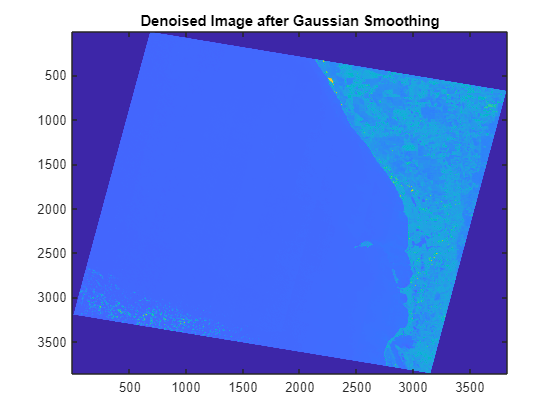

% Apply Gaussian smoothing to reduce noise
sigma = 1;  % Defines the standard deviation for Gaussian smoothing
smoothedData = imgaussfilt3(dataCube, sigma);
% Applies Gaussian filtering to the data cube to smooth and reduce high-frequency noise

% Visualize one of the reflectance bands (e.g., Band 4)
figure;
imagesc(smoothedData(:, :, 4));  % Displays Band 4 (after smoothing)
title('Denoised Image after Gaussian Smoothing');

% Visualizes the smoothed image of Band 4 for inspection


## K Means Clustering

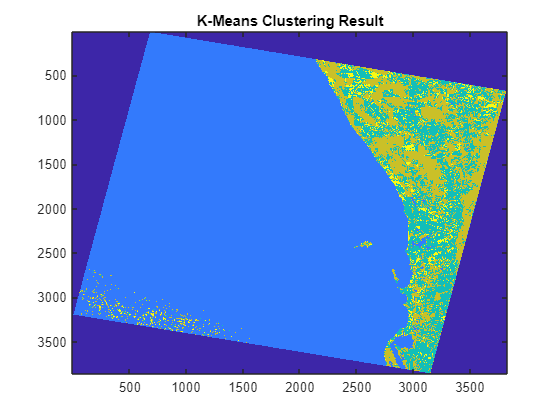

% Reshape data cube for clustering
[numRows, numCols, numBands] = size(smoothedData);  % Retrieves the size of the smoothed data
reshapedData = reshape(smoothedData, [], numBands);  % Reshapes the data cube into a 2D array for clustering

% Perform K-Means clustering to segment data
numClusters = 5;  % Number of clusters (i.e., segments)
[clusterIdx, ~] = kmeans(reshapedData, numClusters, 'MaxIter', 1000);
% Performs K-means clustering to segment the data into 5 clusters based on the spectral properties

% Reshape clustering results back to image dimensions
clusteredImage = reshape(clusterIdx, numRows, numCols);
% Reshapes the clustering results into the image dimensions to visualize the segmentation

% Visualize clustering result
figure;
imagesc(clusteredImage);  % Displays the clustered image
title('K-Means Clustering Result');

% Visualizes the result of the K-means clustering


## Applying Matched Filter

% Define CO2 spectral signature (example profile based on known absorption patterns)
co2Signature = [0.02, 0.03, 0.04, 0.05, 0.04, 0.03, 0.02, 0.01]; 
% Defines a typical CO2 absorption spectral profile across the bands

% Initialize CO2 detection map
co2DetectionMap = zeros(numRows, numCols);
% Initializes an empty map to store CO2 detection results for each pixel

% Perform matched filtering to detect CO2
for c = 1:numClusters
    % Extract pixels belonging to the current cluster
    clusterPixels = reshapedData(clusterIdx == c, :);
    
    % Compute mean spectrum for the cluster
    meanSpectrum = mean(clusterPixels, 1);  % Average spectrum for the current cluster
    
    % Normalize spectral profiles
    meanSpectrum = meanSpectrum / norm(meanSpectrum);  % Normalizes the cluster's mean spectrum
    co2Signature = co2Signature / norm(co2Signature);  % Normalizes the CO2 spectral signature
    
    % Calculate matched filter response
    matchedFilter = co2Signature' * meanSpectrum / (norm(meanSpectrum)^2);  % Computes filter response
    filterResponse = reshapedData * matchedFilter;  % Applies the matched filter
    
    % Assign response values to the map
    co2DetectionMap(clusterIdx == c) = filterResponse(clusterIdx == c);
end
% Performs matched filtering on each cluster to detect CO2 based on the spectral signature


## Visualization

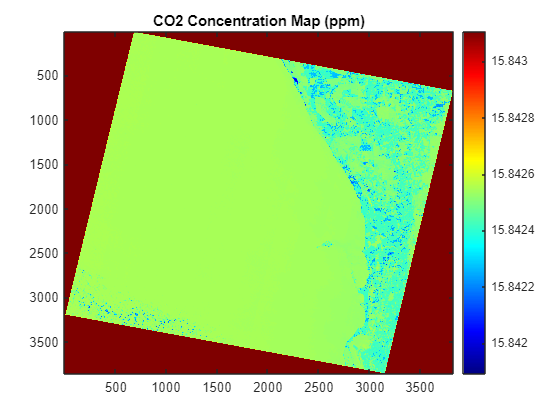

% Define scaling factor to convert filter response to ppm
scalingFactor = 400;  % Scaling factor for converting matched filter response to CO2 concentration in ppm

% Convert CO2 detection map to ppm
co2_ppm_map = co2DetectionMap * scalingFactor;
% Converts the matched filter response to parts per million (ppm) CO2 concentration

% Apply thresholding for anomalies in ppm
ppm_threshold = prctile(co2_ppm_map(:), 70);  % Defines the threshold for detecting CO2 anomalies
co2_ppm_anomalies = co2_ppm_map > ppm_threshold;  % Identifies anomalies where CO2 exceeds the threshold

% Visualize CO2 concentration in ppm
figure;
imagesc(co2_ppm_map);  % Displays the CO2 concentration map
colormap('jet');  % Applies a color map for better visualization of the CO2 levels
title('CO2 Concentration Map (ppm)');  % Adds a title to the plot
colorbar;  % Displays a colorbar to indicate the scale of ppm

## Mapping on World Map

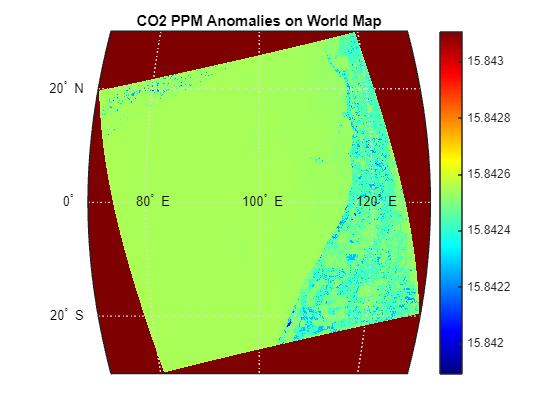

% Define geographic boundaries for the map
minLat = -30; 
maxLat = 30;  
minLon = 70;  
maxLon = 130; 
% Specifies the geographic region for mapping (latitude and longitude boundaries)

% Create geographic coordinates
lat = linspace(minLat, maxLat, numRows);  % Generates latitude values for the map
lon = linspace(minLon, maxLon, numCols);  % Generates longitude values for the map
[LON, LAT] = meshgrid(lon, lat);  % Creates a meshgrid of latitude and longitude for mapping

% Visualize CO2 ppm anomalies on world map
figure;
worldmap([minLat, maxLat], [minLon, maxLon]);  % Creates a world map based on the defined lat/lon boundaries
load coastlines;  % Loads coastlines for accurate map plotting
plotm(coastlat, coastlon, 'k');  % Plots the coastlines on the map
geoshow(LAT, LON, double(co2_ppm_map), 'DisplayType', 'texturemap');  % Displays the CO2 anomalies on the map
colormap('jet');  % Applies a color map for visualization
title('CO2 PPM Anomalies on World Map');  % Adds a title to the map visualization
colorbar;  % Displays a colorbar to indicate the scale of ppm